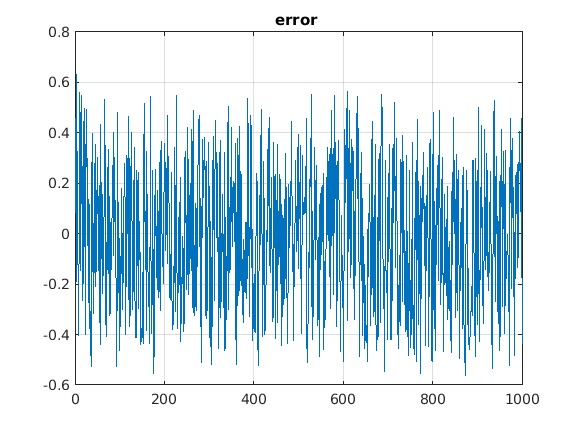

clc;
clear all;
close all;

N=1000;
t=[0:N-1];
ita=10^4;
I=ones(1,N);
R=ita*I;
input = xlsread('data_for_system_identification.xlsx','Sheet1');
%for output without noise 
x=input(:,1);
out=input(:,3);
w=zeros(1,N); 
MSE_RLS = zeros(N,1);
z=[];
for i=1:N
   y(i) = w(i)' * x(i);
   e(i) = out(i) - y(i);
   z(i) = R(i) * x(i);
   q = x(i)' * z(i);
   v = 1/(1+q);
   zz(i) = v * z(i);
   w(i+1) = w(i) + e(i)*zz(i);
   R(i+1) = R(i) - zz(i)*z(i);
   se=e.^2;
   MSE_RLS(i) = norm(MSE_RLS(i)+(abs(e).^2));

end
MSE_RLS = MSE_RLS./R;

plot(e(1:1000));title('error ');grid on 

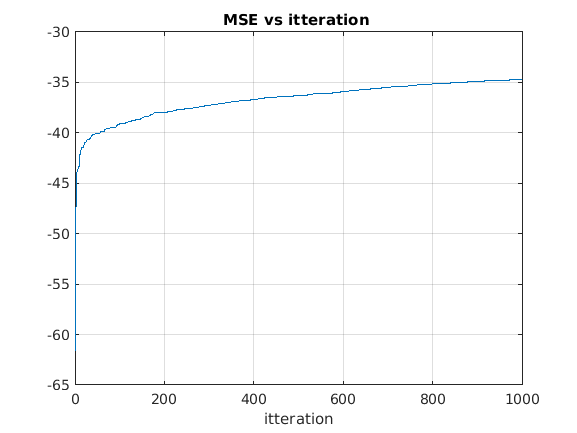

plot(10*log10(MSE_RLS(1:1000)));xlabel('itteration');title('MSE vs itteration ');grid on 

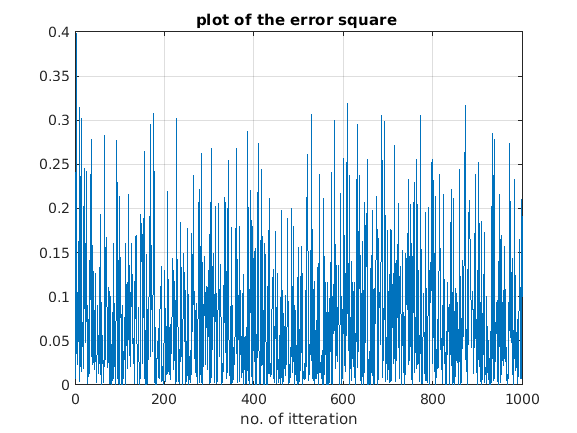

figure 
z=[z,se];
plot(se);
xlabel('no. of itteration');
title('plot of the error square ');
grid on ;